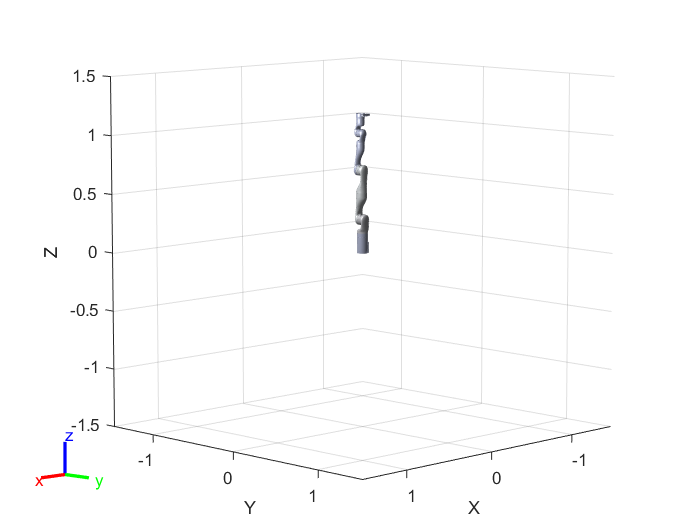

Unrecognized function or variable 'robotState'.

% connect to mqtt %
Address = "tcp://broker.hivemq.com";
Topic = "TGR/data";
mqClient = mqttclient(Address);
subscribe(mqClient,Topic);
% end %

%load robot%
gen3 = loadrobot("kinovaGen3", "DataFormat", "row", "Gravity", [0 0 -9.81]); %collect data in row and add gravity -9.81m/s2
Home = homeConfiguration(gen3); % first pose
EE = "EndEffector_Link"; % set end effector
   

%get data%
%form = {"rx":0, "ry":0, "rz":0, "px":0, "py":0, "pz":0}
while(true)

    data = read(mqClient);
    pause(5)
    r = jsondecode (data.Data);
        rx = 0.5;
        ry = 0.3;
        rz = 0.6;
        px = 0.7;
        py = 0.4;
        pz = 0.9;
        
    pause(5)
    %initiation
  Rx = [1 0 0 0];
  Ry = [0 1 0 0];
  Rz = [0 0 1 0];
  P = [0 0 1];


  % Set up param %    
  Rx = [1 0 0 rx];
  Ry = [0 1 0 ry];
  Rz = [0 0 1 rz];
  P = [px py pz];

  jointInit = Home;
  no_Joint = numel(Home); %number of joints
  timeStep = 0.1; % calculation time
  v = 0.1; %speed of the movement
  

% use task space trajectory w/ Inverse kinematics to move according to M5              
% SYNTAX transform = getTransform(robot,configuration,bodyname)
Pose0 = getTransform(gen3,Home,EE);
PoseFinal = trvec2tform(P)*axang2tform(Rx)*axang2tform(Ry)*axang2tform(Rz);
t0 = 0;

Type = 'JointSpace';
switch Type
    case 'TaskSpace'
        %use 'norm' to find distance btw two points
            s = norm(tform2trvec(Pose0)-tform2trvec(PoseFinal));
            tf = (s/v) - t0 ; % t
            %imeSpan = t0:timeStep:tf;
            %tau = [timeSpan(1); timeSpan(end)];
            %timeSpan = transpose(timeSpan);
            
            tau = [1 1.1 1.2 1.3 1.4 1.5 1.6];
            
            %interpolate
            [taskWaypoints,taskVelocities] = transformtraj(Pose0,PoseFinal,tau); 
            motionModel = taskSpaceMotionModel("RigidBodyTree", gen3, "EndEffectorName", "EndEffector_Link"); % move w/ PD in ts model
            input()

            %TODO: try setting these Ks
            MotionModel.Kp(1:3,1:3) = 0;
            MotionModel.Kd(1:3,1:3) = 0;

            q0 = Home; 
            q0d = zeros(size(q0));
        
            [t,robotState] = ode15s(@(t,state)derivative(motionModel,tau,Pose0,PoseFinal, t,state), tau, [q0,q0d]);
            
            % plot %
            show(gen3,Home,'PreservePlot',false,'Frames','off');
            for i=1:length(timeSpan)
            tNow= timeSpan(i);
            % Interpolate simulated joint positions to get configuration at current time
            configNow = interp1(tf,robotState(:,1:no_Joint),tNow);
            poseNow = getTransform(gen3,configNow,EE);
             show(robot,configNow,'PreservePlot',false,'Frames','off');
            print("InitPose: ", Home, "PoseNow: ", poseNow)
            end
            
    case 'JointSpace'
            s = norm(tform2trvec(Pose0)-tform2trvec(PoseFinal));
            tf = (s/v) - t0 ; % t
            timeSpan = t0:timeStep:tf;
            %timeSpan = transpose(timeSpan);
            %tau = [timeSpan(1); timeSpan(end)];
            tau = [1 1.1 1.2 1.3 1.4 1.5 1.6];
            ik = inverseKinematics('RigidBodyTree',gen3); %xyz interactable
            ikW = [1 1 1 1 1 1];

            Init = jointInit; %set initial joint config
            Jf = ik(EE,PoseFinal,ikW,Init);
            % limit joint transformation in range -pi and pi
            wrappedJointFinal = wrapToPi(Jf);
            % interpolate respect to joint limit and use cubic polynomial
            
            ctrlpoints = [jointInit',wrappedJointFinal'];
            ctrlpoints = transpose(ctrlpoints);
            jointConfigArray = cubicpolytraj(ctrlpoints,tau,timeSpan);
            q0 = Home; 
            qd0 = zeros(size(q0));

            % plot %
            show(gen3,Home,'PreservePlot',false,'Frames','off');
            for i=1:length(timeSpan)
            tNow= timeSpan(i);
            % Interpolate simulated joint positions to get configuration at current time
            configNow = interp1(tf,robotState(:,1:no_Joint),tNow);
            poseNow = getTransform(gen3,configNow,EE);
            show(robot,configNow,'PreservePlot',false,'Frames','off');
            disp(Home)
            disp(PoseFinal)
  
            end


    otherwise
        error('invalid trajectory type input');

end

end